## Run sections below one by one

## Setup

clearvars, clc, close all

Specify paths:

- To FreeSurfer home directory ($FREESURFER_HOME)

cfg.dir_fs = '/home/qian/research/freesurfer';

- To FreeSurfer subject directory ($SUBJECTS_DIR)

cfg.dir_fs_subjects = '/home/qian/research/fs_subjects';

FREESURFER_HOME and SUBJECTS_DIR can be found in the command line outputs when you source FreeSurfer using *SetUpFreeSurfer.sh*

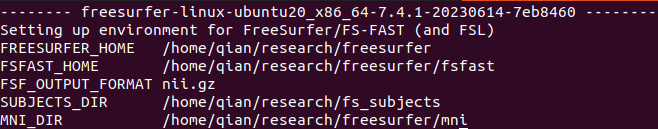

Type patient ID below:

pat.id  = "TWH224";

Set up paths:

elec_loc_path       = matlab.desktop.editor.getActiveFilename;
elec_loc_path_parts = split(elec_loc_path, filesep);
cfg.dir_el          = strjoin(elec_loc_path_parts(1:end-1), filesep);
addpath(fullfile(cfg.dir_el, 'functions'))
[cfg, pat] = el_init(cfg, pat);     

Load iel output from elec_loc

el_get_elec

pat.dir

ans = struct with fields:
              fs: "/home/qian/research/fs_subjects/TWH224"
          fs_mri: "/home/qian/research/fs_subjects/TWH224/mri"
         fs_surf: "/home/qian/research/fs_subjects/TWH224/surf"
              el: "/home/qian/research/fs_subjects/TWH224/elec_loc"
         el_bids: "/home/qian/research/fs_subjects/TWH224/elec_loc/BIDS_outputs"
    el_bids_anat: "/home/qian/research/fs_subjects/TWH224/elec_loc/BIDS_outputs/anat"
    el_bids_ieeg: "/home/qian/research/fs_subjects/TWH224/elec_loc/BIDS_outputs/ieeg"


pat.id

ans = "TWH224"